# DATA VISUALIZATION (COS 701)

**Lionel Amuzu**

## Assignment 1

## a:

Write a computer code thats produces random numbers that are exponentially distributed take $p(x)=a \exp{(-bx)}$.

step 0: Creating a uniformly distributed random numbers and visualizing the pdf $p(x)$

n=10000;   % number of random # (0,1)
p = @ (x,a,b) a*exp(-b*x) %pdf

p = function_handle with value:
    @(x,a,b)a*exp(-b*x)


xi=rand(1,n)          % uni rand #

xi =     0.2120    0.4561    0.4217    0.8980    0.9600    0.1303    0.0791    0.7859    0.9818    0.3518    0.9938    0.0993    0.1586    0.6844    0.0190    0.5265    0.2832    0.0371    0.1906    0.5383    0.7484    0.4062    0.1962    0.5796    0.4809    0.3169    0.6350    0.7884    0.1839    0.9221    0.4725    0.5266    0.4810    0.5088    0.2776    0.0427    0.2076    0.2606    0.7824    0.0984    0.5395    0.1271    0.5506    0.6396    0.1146    0.8701    0.8467    0.2711    0.6257    0.6195


y1=p(xi,0.5,0.5);
y2=p(xi,1,1);
y3=p(xi,1.5,1.5);
y4=p(xi,0.5,1);

## visualize the pdf

% plot(xi,y2,'.',xi,y3,'.',xi,y4,'.',"LineWidth",1)
% 
% set(gca,"FontSize",24,"FontName","Times")
% xlabel("$x$","Interpreter","latex")
% ylabel("$p(x)$","Interpreter","latex")
% xlim([0.000 1.000])
% ylim([0.00 1.50])
%legend('$a=b=1$','$a=b=1.5$','$a=0.5~ b=1$',"Interpreter","latex")

**step1:** Convert pdf $p(x)$ to cdf $P(x)=\int_{0}^{x}{p(x)}$, $x \to \infty$


$$P(x)=\int_{0}^{x}a\exp{(-bt)}dt=\frac{a}{b}(1-\exp{(-bx)})$$


if $y=p(x)$and $y$ is invertible(one-to-one) then $x$ can be written in terms of $y$ as $x=p(y)$ 


$$P^{-1}(x)=-\frac{1}{b}\ln{(1-\frac{b}{a}x)}=-(\ln(\frac{a}{b}-x)+\ln\frac{b}{a})/b$$


%cdf=int(p,x,[0,x])
%invP=finverse(cdf)

## inverse of the cdf

U= @(x, a, b) (-log((a/b)-x) + log(b/a))/b

U = function_handle with value:
    @(x,a,b)(-log((a/b)-x)+log(b/a))/b


%-log(1 - (b*x)/a)/b
U=U(xi,1,1)

U =     0.2382    0.6091    0.5477    2.2826    3.2182    0.1396    0.0824    1.5414    4.0068    0.4335    5.0860    0.1045    0.1727    1.1533    0.0192    0.7477    0.3329    0.0378    0.2114    0.7728    1.3799    0.5212    0.2184    0.8666    0.6556    0.3811    1.0078    1.5529    0.2032    2.5525    0.6395    0.7477    0.6558    0.7108    0.3252    0.0436    0.2326    0.3019    1.5252    0.1036    0.7754    0.1360    0.7998    1.0205    0.1217    2.0410    1.8751    0.3162    0.9828    0.9663


## visualize the exponential distribution curve

% plot(xi,U,'b.',"LineWidth",2)
% 
% set(gca,"FontSize",24,"FontName","Times")
% xlabel("$x$","Interpreter","latex")
% ylabel("$P^{-1}(x)$","Interpreter","latex")
%legend('$a=b=1$',"Interpreter","latex")

## More visualization (Histogram)

NumBins=50;
Binlimits=[min(U) max(U)];
Binwidths=(Binlimits(2)-Binlimits(1))/(NumBins-1);
BinEdge= Binlimits(1):Binwidths:Binlimits(2);%UNIFORM # ABOUT THE DISTRIBUTION


## creating frequency table for distribution


freq=zeros(1,NumBins);%frequency(tally)
for i = 1:n
    for j = 2:NumBins
        if U(i) <= BinEdge(j) && U(i) > BinEdge(j-1)
            freq(j-1) = freq(j-1)+1;
        end
    end
end

## Visualize

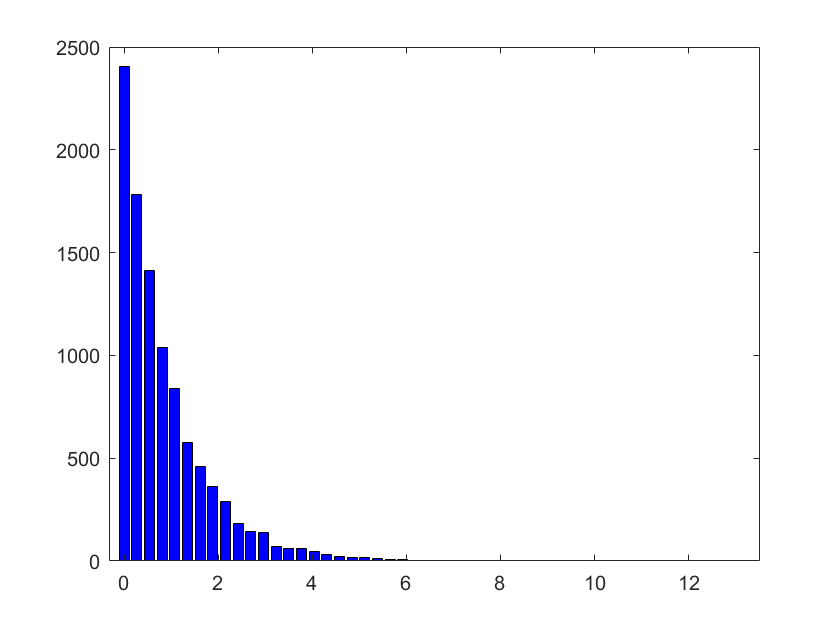

bar(BinEdge,freq,'b')

% hold on
% histogram(U)
% ylabel("number of observation","Interpreter","latex")
% hold off
% 
%legend('construted','Matlab')

## b:

use the Box-muller  transformation transformation to generate random variates that are normally distributed, $\mu=0$ and variance $\sigma^{2}$.

    x1=rand(n,1); %Uni # (0,1)
    x2=rand(n,1); 
    %Box-Muller Transform
    U1=sqrt(-2*log(x1)).*cos(2*pi*x2); %normally dis (0,1)
    U2=sqrt(-2*log(x1)).*sin(2*pi*x2); 

## visuals

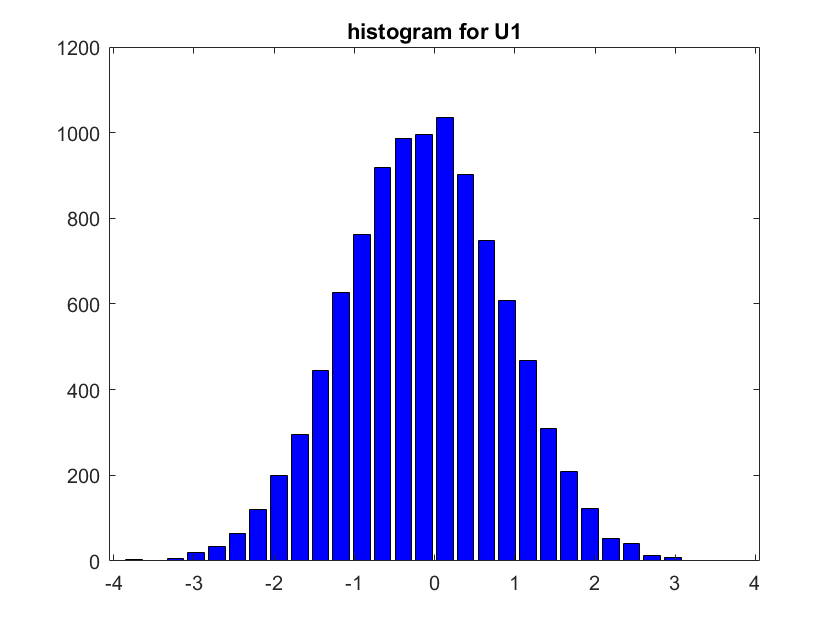

NumBins=30;
Binlimits=[min(U1) max(U1)];
Binwidths=(Binlimits(2)-Binlimits(1))/(NumBins-1);
BinEdge= Binlimits(1):Binwidths:Binlimits(2);

freq=zeros(1,NumBins);%frequency(tally)
for i = 1:n
    for j = 2:NumBins
        if U1(i) <= BinEdge(j) && U1(i) >= BinEdge(j-1)
            freq(j-1) = freq(j-1)+1;
        end
    end
end

bar(BinEdge,freq,'b')

title('histogram for U1')

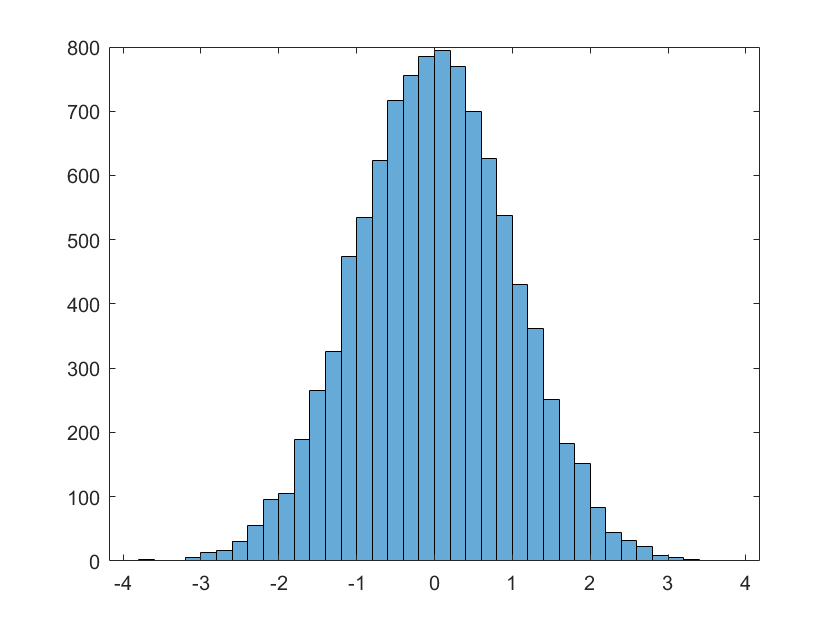

histogram(U1)

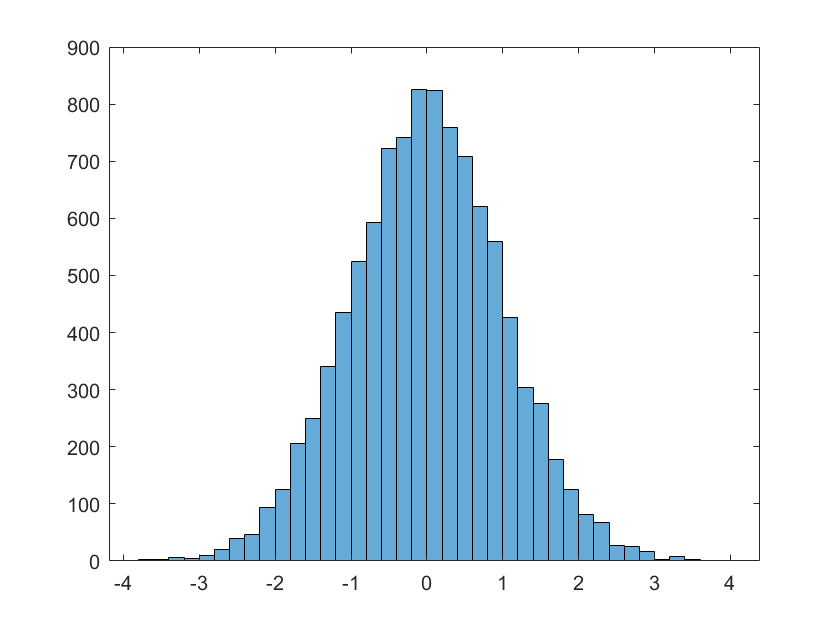

histogram(U2)

## C:

Use the central limit theorem or the law of large numbers to generate normally or Gaussian distributed random numbers. Assume that the mean value and the standard deviation of the normal distribution are given by 0 and 1, respectively.

## Sum of n random sample u~[0,1]

$X_{1}+X_{2}+\cdot \cdot \cdot + X_{n} \\ [X_1 X_1+X_2...]$     a column contains

N = 100000;        % num(random sample) 
m = 1000;            % len(random samle)
X = zeros(1,m);     % initial X
Xn=rand(m,N);       %each column is a random sample of len(m)
Xc=cumsum(Xn);       %cumulative sum columnwise
Xnebar=zeros(m,N);    %cumulative mean initialized
for i = 1:m
    Xnebar(i,:) = Xc(i,:)/i;
end

## Sum of n random sample u~[0,1]

$X_{1}+X_{2}+\cdot \cdot \cdot + X_{n} \\ [X_1 X_1+X_2...]$     a column contains


Xne=zeros(m,N); 
Xne(:,1)=Xn(:,1);
for i=1:N-1
    Xne(:,i+1)=Xne(:,i)+Xn(:,i+1);
end


Xnebar=zeros(m,N);   %cumulative mean X1+X2..
mu=mean(Xne)         % mu

mu = 	1.0e+04 *

    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0010    0.0010    0.0011    0.0011    0.0012    0.0012    0.0013    0.0013    0.0014    0.0014    0.0015    0.0015    0.0016    0.0016    0.0016    0.0017    0.0017    0.0018    0.0019    0.0019    0.0019    0.0020    0.0020    0.0021    0.0021    0.0022    0.0023    0.0023    0.0023    0.0024    0.0024    0.0025


va=var(Xne);        %variance
for i = 1:N
    Xnebar(:,i) = Xne(:,i)/i; %
    mu(i)=mu(i)/i;        %The sum  X_{1}+...+X_{n}} has mean  n\mu variance  n\sigma ^{2}}
    va(i)=va(i)/i;        
end

## Guassian distribution

${\displaystyle {\bar {X}}_{n}={\frac {X_{1}+\cdots +X_{n}}{n}}}$ ensures that as $n\to\infty,  ~~ \frac{\sqrt{n}}{\sigma}(\bar{X}_{n}-\mu)$ approaaches ~ $N[0,\sigma^{2}]$


jm=100 % just a jump you dont want to see the size of that matrix 

jm = 100

Nd=zeros(m,floor(N/jm));
for j=1:jm:N
    Nd(:,j)=(sqrt(N/va(j)^2))*Xnebar(:,j)-mu(j);
end
Nd=normalize(Nd);

## visual

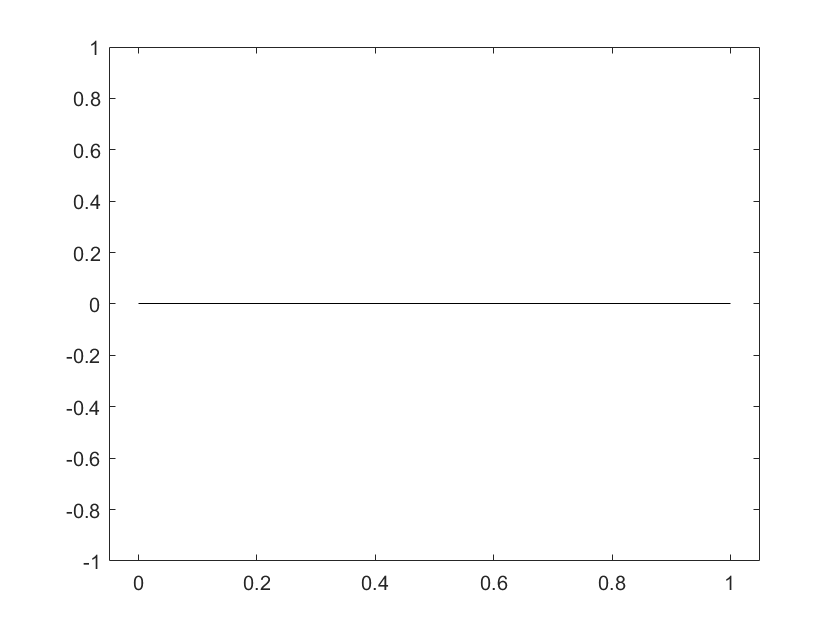

histogram(Nd(:,2))

histogram(Nd(:,5))

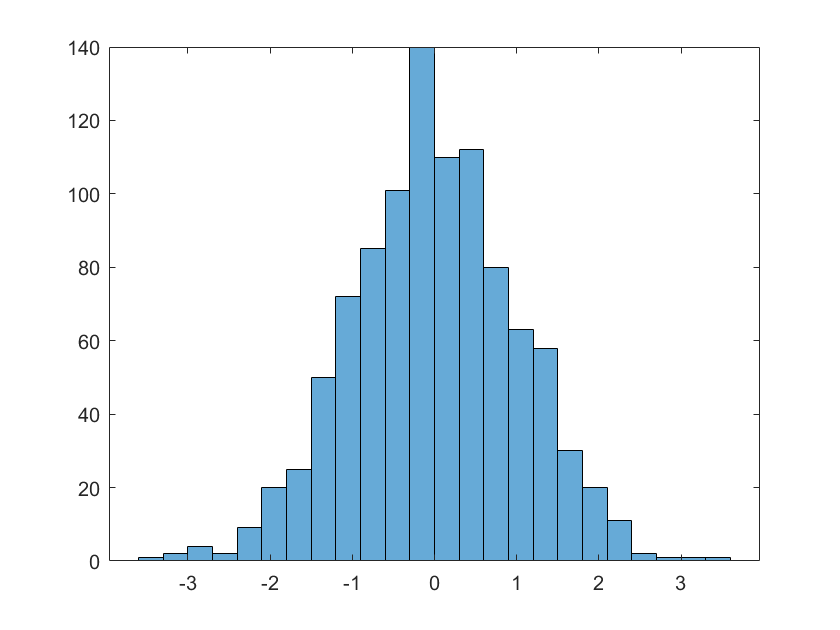

histogram(Nd(:,end))

## d:

Generate the following distribution of random numbers by using the inverse transform method. $p(x)=\frac{x}{\sigma^2}\exp{(\frac{-x^{2}}{2\sigma^{2}})}$

n = 10000;     
x = rand(n,1);   %u[0,1]
sigma = 1;          
U = sigma*sqrt(-2*log(x));
NumBins=30;a=2;b=2;
Binlimits=[min(U) max(U)];
Binwidths=(Binlimits(2)-Binlimits(1))/(NumBins-1)

Binwidths = 0.1467

BinEdge= Binlimits(1):Binwidths:Binlimits(2)%UNIFORM # ABOUT THE DISTRIBUTION

BinEdge =     0.0097    0.1564    0.3031    0.4498    0.5965    0.7433    0.8900    1.0367    1.1834    1.3301    1.4768    1.6235    1.7702    1.9169    2.0636    2.2103    2.3571    2.5038    2.6505    2.7972    2.9439    3.0906    3.2373    3.3840    3.5307    3.6774    3.8241    3.9709    4.1176    4.2643



freq=zeros(1,NumBins);%frequency(tally)
for i = 1:n
    for j = 2:NumBins
        if U(i) < BinEdge(j) && U(i) >= BinEdge(j-1)
            freq(j-1) = freq(j-1)+1;
        end
    end
end

## Visualize

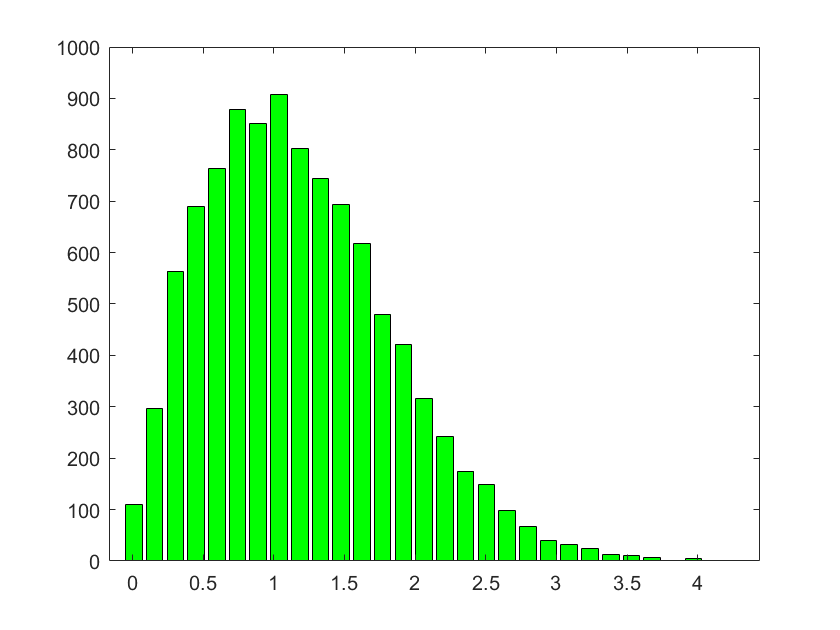

bar(BinEdge,freq,'g')